clc;
clear;
% Get the handle of the command window
commandwindow;
% Model 1 theta  = 0 degree
% Model 2 theta  = 30 degree
% Model 3 theta  = 45 degree
% Model 4 theta  = 90 degree
theta  = input('Enter the Fibre Orientation in Degree:  ');
disp(['Fibre Orientation of:  ', num2str(theta),'  Degree'])

Fibre Orientation of:  0  Degree


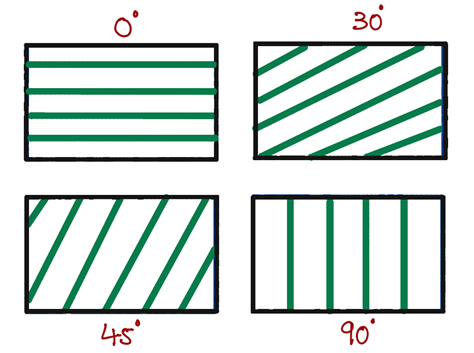

% Handbook values AS4 glass Epoxy
% Fiber properties
Ef = 235*1000;  % MPa
vf = 0.20;
% Matrix properties
Em = 4.6*1000;   % MPa
vm = 0.36;
% Volume Fraction
VF = 0.60;

[E11,E22,G12,nu12] = StdMechanics(Ef,vf,Em,vm,VF);

% Table values
E11T = 126*1000; % MPa
E22T = 11*1000; % MPa
nu12T = 0.280;
G12T = 6600; % MPa

% Create a table to compare computed values with table values and errors
properties = {'E11', 'E22', 'G12', 'nu12'};
computed_values = [E11; E22; G12; nu12];
table_values = [E11T, E22T, G12T, nu12T];

% Display the comparison in a table
TableElastic = table(properties', computed_values, table_values', 'VariableNames', {'Property', 'Computed_Value', 'Table_Value'});
disp(TableElastic);

    Property    Computed_Value    Table_Value
    ________    ______________    ___________

    {'E11' }      1.4284e+05       1.26e+05  
    {'E22' }           11172          11000  
    {'G12' }          4121.2           6600  
    {'nu12'}           0.264           0.28  



**Geometry**

thickness = 5 % mm

thickness = 5

width =  10   % mm

width = 10

A   = (thickness*width)*10^-6

A = 5.0000e-05

AE  = A*E11

AE = 7.1420

% Domain of X
x0 = 0;
xL = 1;
L = xL; % Length

**Differential Equations**


$$a\frac{d^2 u}{dx^2 }+b\frac{du}{dx}+c{\left(x\right)}u=f{\left(x\right)}$$


a = AE;
% In spring case for a =1 only it is working, for plotting exact solution
b = 0;
c =0.001;
f =0;

**Order of Interpolation Function & No of Elements**

P = 2; % Only works till P = 6  % Gauss points restriction
% P Order of Interpolation Function for element
ndofel = P+1;
% No of elements
e = 5;

**Boundary Values**

% Get the handle of the command window
commandwindow;

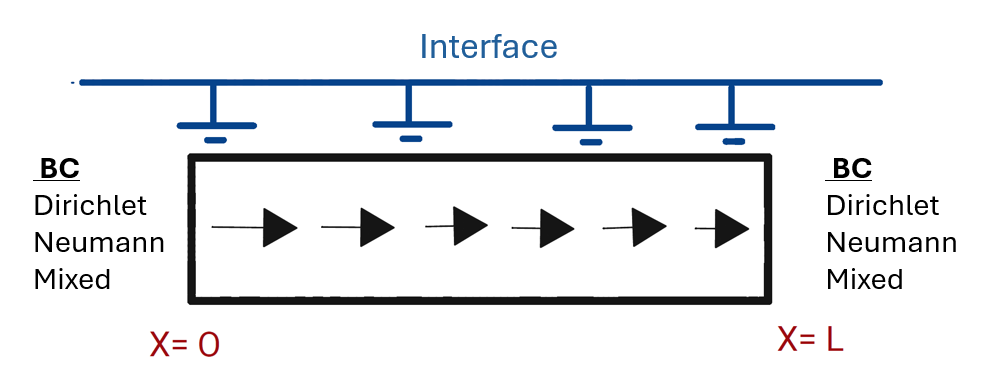

**Case - 1**

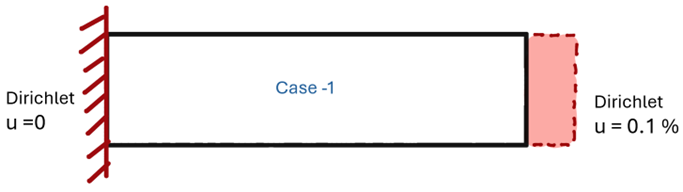

**Case - 2**

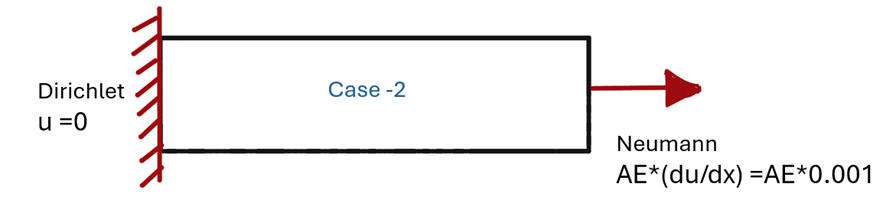

**Case - 3**

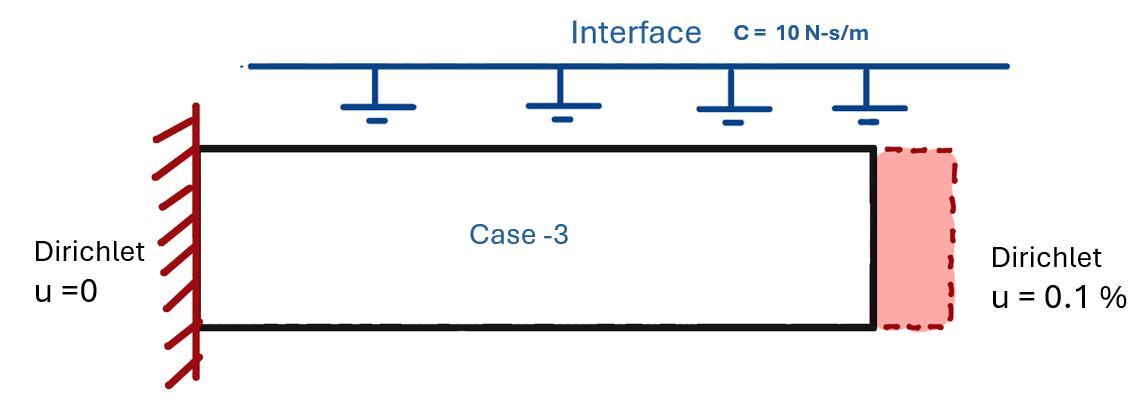

% Prompt the user to input boundary conditions at x0
prompt_x0 = 'Enter the type of boundary condition at x0 (1. Dirichlet, 2. Neumann, 3. Spring): ';
type_x0 = input(prompt_x0);

switch type_x0
    case 1
        u0 = input('Enter the Dirichlet value u at x0: ');
    case 2
        Q0 = input('Enter the Neumann value (du/dx) at x0: ');
    case 3
        K0 = input('Enter the spring constant K at x0: ');
        Del0 = input('Enter the spring displacement Del at x0: ');
    otherwise
        error('Invalid boundary condition type at x0');
end


% Prompt the user to input boundary conditions at xL
prompt_xL = 'Enter the type of boundary condition at xL (1. Dirichlet, 2. Neumann, 3. Spring): ';
type_xL = input(prompt_xL);

switch type_xL
    case 1
        uL = input('Enter the Dirichlet value u at xL: ');
    case 2
        P1 = input('Enter the Neumann value (du/dx) at xL: ');
    case 3
        K1 = input('Enter the spring constant K at xL: ');
        Del1 = input('Enter the spring displacement Del at xL: ');
    otherwise
        error('Invalid boundary condition type at xL');
end

% Prompt the user to input information about a point load
prompt_pointLoad = 'Is there a point load present? (1.yes, 2.no): ';
pointLoadResponse = input(prompt_pointLoad); % Numeric input

switch pointLoadResponse
    case 1
        PL1 = input('Enter the value of the point load: ');
        PL1_loc = input('Enter the Point Load Location: ');
    case 2
        disp('No point load present, continuing with the rest of the code.');
    otherwise
        error('Invalid response for the presence of a point load. Please enter 1.yes or 2.no.');
end

No point load present, continuing with the rest of the code.



%Continue with the remaining code...

if exist('PL1_loc', 'var') && exist('PL1', 'var')
    F_location = PL1_loc;  
    x_vector = GlobalLocation(x0, xL, P, e);
    
    [incremented_e, decremented_e, valuePL] = adjust_e(x_vector, P, x0, xL, F_location, e);
     if valuePL == 1

        % Continue with the rest of the code as usual if valuePL is 1.
        adjusted_e = choose_e(incremented_e, decremented_e, e);
        x_vector1 = GlobalLocation(x0, xL, P, adjusted_e);
        PL1_index = find_indices(x_vector1, F_location);
        disp(['Indices where x_vector == F_location: ', num2str(PL1_index)]);

    elseif valuePL == 2
       
        prompt_adjust = ['For given Point load location and element number Their is No nodal point to keep Point load' ...
            ' Do you want to adjust the element value? (1.yes, 2.no): '];
        adjustResponse = input(prompt_adjust);
        
        if adjustResponse == 1
            adjusted_e = choose_e(incremented_e, decremented_e, e);
            disp(['Adjusted New elements is: ', num2str(adjusted_e)]);
            x_vector1 = GlobalLocation(x0, xL, P, adjusted_e);
            PL1_index = find_indices(x_vector1, F_location);
            disp(['Indices where x_vector == F_location: ', num2str(PL1_index)]);

        elseif adjustResponse == 2

            disp('Exiting the program.');
            return; % This will exit the script

        else
            error('Invalid response. Please enter 1 for yes or 2 for no.');
        end
    else
        error('Unexpected valuePL. Expected values are 1 or 2.');
     end
end


if exist('adjusted_e', 'var')
    e = adjusted_e;
end

**FEM Solver**

[K_global_D_bc, Fv, S, X_nodes] = FEM_Processor(P, e, L, a, b, c, f);

Gv = sym(zeros(S, 1));
Sv = sym(zeros(S, 1));

if exist('PL1_index', 'var') && exist('PL1_loc', 'var') && exist('PL1', 'var')
    Gv(PL1_index) = PL1
end

% For X0 left node we need to add correction factor
if exist('Q0', 'var') 
    Q0 = AE *Q0
    Gv(1) = -Q0;   % Correction factor Added
end

if exist('K0', 'var') && exist('Del0', 'var')
    Sv(1) = -K0 * Del0;    % Correction factor Added
    K_global_D_bc(1, 1) = K_global_D_bc(1, 1) + K0;
end

if exist('P1', 'var') 
    P1 = AE *P1
    Gv(end) = P1;
end

P1 = 0.0071


if exist('K1', 'var') && exist('Del1', 'var')
    Sv(end) = K1 * Del1;  
    K_global_D_bc(end, end) = K_global_D_bc(end, end) + K1;
end

Gv = Gv *a;

RHS = Fv + Gv + Sv;

% Handle boundary conditions at x0
if exist('u0', 'var') 
    K_global_D_bc(1, :) = [1, zeros(1, S-1)];  % u0 = 0
    RHS(1) = u0;  % RHS of equation
end

% Handle boundary conditions at xL
if exist('uL', 'var') 
    K_global_D_bc(end, :) = [zeros(1, S-1), 1];  % uL = 0
    RHS(end) = uL;  % RHS of equation
end  

K_global_D_bc;
RHS;

u_nodes = double(K_global_D_bc \ RHS);% u at nodal points
% disp("-------------------------------------------------------------")
% myTable = table(X_nodes, u_nodes, 'VariableNames', {'Nodal Location', 'u node value'});
% disp(myTable);
% disp("-------------------------------------------------------------")

syms x  u_e(x)
%----------------------------------------------------------------------------
deqn = a*diff(u_e,x,2)+b*diff(u_e,x,1)+c*u_e == f;

d_ue(x)= diff(u_e,x);


if exist('Q0', 'var') 
    ic0=d_ue(x0) == Q0;  

elseif exist('K0', 'var') && exist('Del0', 'var')
    ic0=d_ue(x0) == K0 * (Del0+u_nodes(1));    
else
    ic0=u_e(x0) == u0;
end

if exist('P1', 'var') 
    icL=d_ue(xL) == P1;  

elseif exist('K1', 'var') && exist('Del1', 'var')
    icL=d_ue(xL) == K1 * (Del1-u_nodes(end));    
else
    icL=u_e(xL) == uL;
end

u_exact = dsolve(deqn,[ic0 icL]);
u_exact_equation = u_exact

$$u\_exact\_equation = \frac{8234165385902101\,\sqrt{7142}\,\sin\left(\frac{\sqrt{7142}\,x}{7142}\right)}{1152921504606846976\,\cos\left(\frac{\sqrt{7142}}{7142}\right)}$$

%----------------------------------------------------------------------------------
clear u_e(x)

These are the Functions are useful for point load, and adjusting the element number according to point load location 

- lagrange_interpolation

- choose_e

- find_indices

- adjust_e

- uprime

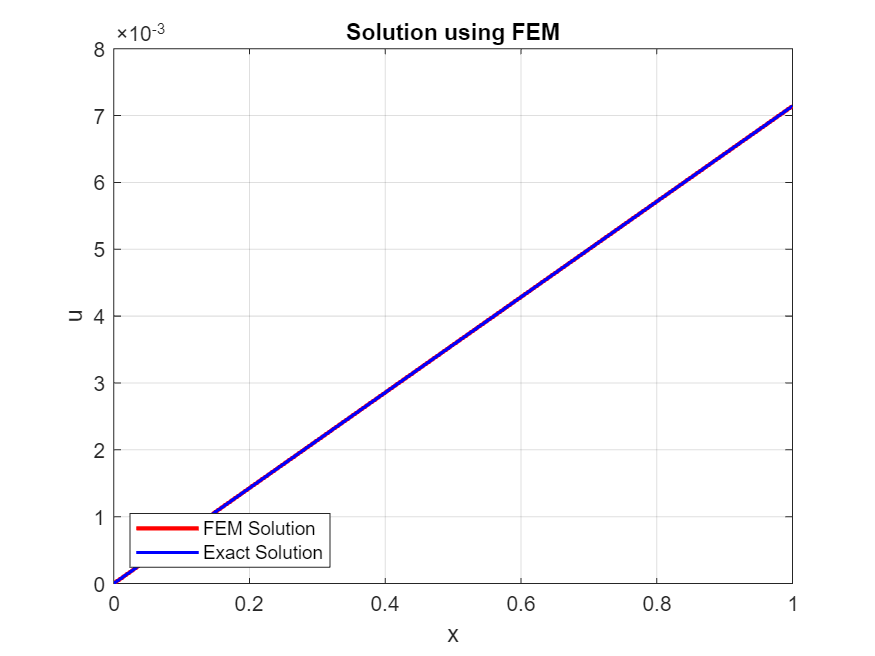

[element_numbers,interpolating_functions,ranges,u_prime_values] = uprime(u_nodes,X_nodes,P,e,S);

% Create and display the table
Table1 = table(element_numbers, interpolating_functions, ranges, ...
          'VariableNames', {'Element Number', 'Interpolating Function', 'Range'});
%disp(Table1);


% myTable1 = table(X_nodes, u_nodes,u_prime_values', 'VariableNames', {'Nodal Location', 'u node value','du/dx'});
% disp(myTable1);
% disp("-------------------------------------------------------------")

%Plot the FDM Solution and the actual solution
figure;
plot(X_nodes, u_nodes, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, u_exact_equation,[x0 xL] ,"b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution using FEM");
legend('Location', 'southwest');
grid on;


du_exact_equation = diff(u_exact_equation,x)

$$du\_exact\_equation = \frac{8234165385902101\,\cos\left(\frac{\sqrt{7142}\,x}{7142}\right)}{1152921504606846976\,\cos\left(\frac{\sqrt{7142}}{7142}\right)}$$

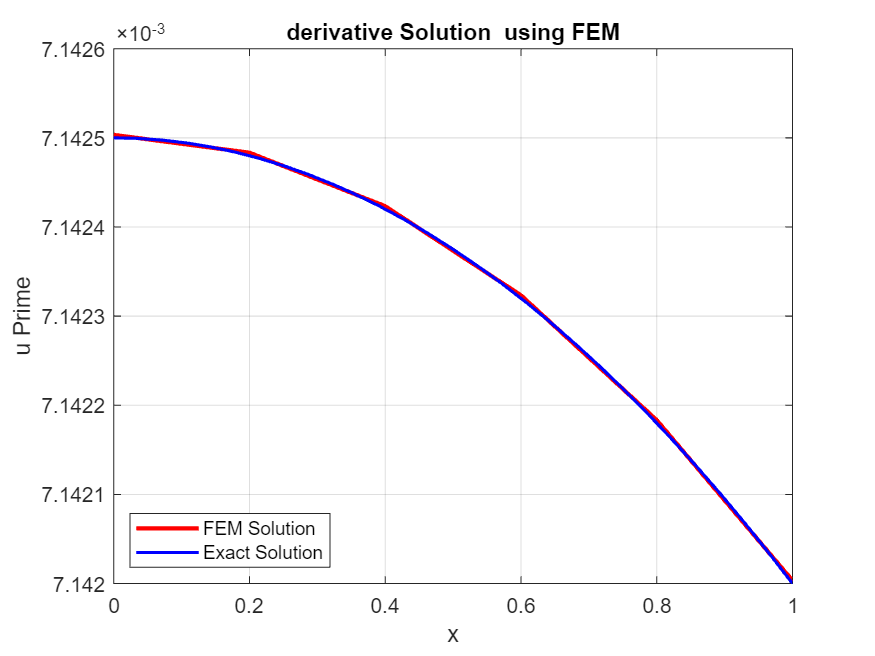


%Plot the FDM Solution and the actual solution
figure;
plot(X_nodes, u_prime_values, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, du_exact_equation,[x0 xL] ,"b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u Prime");
title("derivative Solution  using FEM");
legend('Location', 'southwest');
grid on;


sigmaXXAtNodes = E11 * u_prime_values';

myTable1 = table(X_nodes, u_nodes,u_prime_values',sigmaXXAtNodes, 'VariableNames', {'Nodal Location', 'u node value','du/dx', 'sigma xx'});
disp(myTable1);

    Nodal Location    u node value      du/dx      sigma xx
    ______________    ____________    _________    ________

           0                    0     0.0071425     1020.2 
         0.1           0.00071425     0.0071425     1020.2 
         0.2            0.0014285     0.0071425     1020.2 
         0.3            0.0021427     0.0071425     1020.2 
         0.4             0.002857     0.0071424     1020.2 
         0.5            0.0035712     0.0071424     1020.2 
         0.6            0.0042855     0.0071423     1020.2 
         0.7            0.0049997     0.0071423     1020.2 
         0.8            0.0057139     0.0071422     1020.2 
         0.9            0.0064281     0.0071421     1020.2 
           1            0.0071423      0.007142     1020.2 



disp("-------------------------------------------------------------")

-------------------------------------------------------------



% Find the absolute maximum value
[sigmaXXMaxValue, index] = max(abs(sigmaXXAtNodes));

% Actual maximum value based on absolute
sigmaXYZMaxLOCATION = X_nodes(index);

% Display results
disp(['sigma XX Max Value: ', num2str(sigmaXXMaxValue),'MPa']);

sigma XX Max Value: 1020.2352MPa


disp(['sigma XXMax LOCATION ', num2str(sigmaXYZMaxLOCATION),' mm']);

sigma XXMax LOCATION 0 mm




T1 = T(1,3,theta);

sigmaXYZ = zeros(6,1);

sigmaXYZ(1) = sigmaXXMaxValue;

sigma123 = T1 * sigmaXYZ;

% Example usage:
sigma1 = sigma123(1);
sigma2 = sigma123(2);
sigma3 = sigma123(3);
sigma4 = sigma123(4);
sigma5 = sigma123(5);
sigma6 = sigma123(6);

Yc = 200;
SL = 79;
phio = deg2rad(53);
nT   = -1/(tan(2 * phio));
ST   =  Yc/(2*tan(phio));
nL= nT*(SL/ST);

% Maximum number of angles (assuming the worst case where every angle could potentially result in damage)
maxAngles = 180;
Angles = zeros(1, maxAngles);  % Preallocate with zeros
numValidAngles = 0;  % Counter for valid angles


% Loop over angles from 1 to 180 degrees
for phi = 1:180
    [sigma_N, tau_T, tau_L] = calculate_stresses(sigma1, sigma2, sigma3, sigma4, sigma5, sigma6, phi);

    % Check if sigma_N is non-negative
    if sigma_N >= 0
        % Calculate LHS of the formula
        LHS = (sigma_N / Yc)^2 + (tau_T / (ST - nT * sigma_N))^2 + (tau_L / (SL - nL * sigma_N))^2;
        if LHS >= 1
            numValidAngles = numValidAngles + 1;
            Angles(numValidAngles) = phi;
        end
    else
        LHS1 = (tau_T / (ST - nT * sigma_N))^2 + (tau_L / (SL - nL * sigma_N))^2;
        if LHS1 >= 1
            numValidAngles = numValidAngles + 1;
            Angles(numValidAngles) = phi;
        end
    end
end

% Remove unused zeros from the Angles array
Angles = Angles(1:numValidAngles);

% Check if any valid angles were found and print the results in a table-like format
if numValidAngles > 0
    disp('Damage occurred along the fracture planes, which are oriented at an angle phi relative to the ply normal, at the following phi angles:');
    disp(' phi Angle (Degrees)\n');
    for i = 1:numValidAngles
        fprintf('%14d°\n', Angles(i));
    end
    fprintf('----------------------------------------\n');
else
    disp('No damage happened.');
end

No damage happened.
